files = ["data20", "data-20", "data40", "data-40", "data60", "data-60", "data80", "data-80", "data100", "data-100"]; %
voltages = [20, -20, 40, -40, 60, -60, 80, -80, 100, -100];
k_all = [];
Tm_all = [];

## Plotting for angle and angle_speed = theta and omega

i = 6;
data = readmatrix(files(i));
time=data(:,1);
U = voltages(i)

U = -60

angle=data(:,2)*pi/180;
omega=data(:,3)*pi/180;

figure
plot(time,omega, 'b'); % , 'DisplayName',"real data"
title("omega(t) with -60% voltage")
legend('real data','approximation', 'model')

xlabel("time, s")
ylabel("angle speed, rad/s")
grid on
xlim([0 1]);
hold on

lol0 = [0.1; 0.06];
func1 = @(lol, time) U*lol(1)*(1 - exp(-time/lol(2)));
solver = lsqcurvefit(func1,lol0,time,omega);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


k = solver(1)

k = 0.2065

Tm = solver(2)

Tm = 0.1444

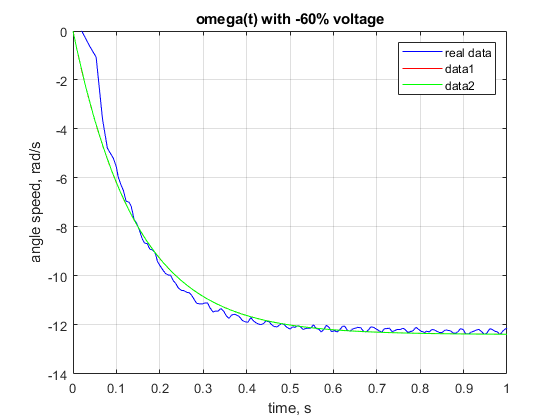


time_apr = 0:0.01:1;
angle_approximation = U*k*(1 - exp(-time_apr/Tm));
plot(time_apr,angle_approximation, 'r'); % , 'DisplayName',"approximation"
hold on
plot(out.omega.Time, out.omega.Data, 'g'); % , 'DisplayName',"model"




figure
plot(time,angle, 'b'); % , 'DisplayName',"real data"
title("angle(t) with -60% voltage")
legend('real data','approximation', 'model')


xlabel("time, s")
ylabel("angle , rad")
grid on
xlim([0 1]);
hold on

lol1 = [0.1; 0.06]; % k Tm

func2 = @(lol, time) U*lol(1)*(time - lol(2)*(1 - exp(-time/lol(2))));
solver = lsqcurvefit(func2,lol1,time,angle);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


k = solver(1)

k = 0.2072

Tm = solver(2)

Tm = 0.1436

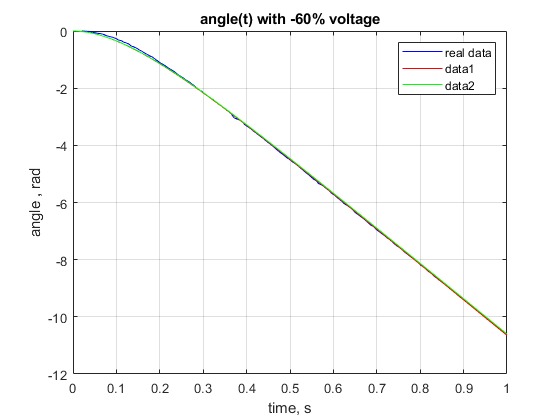


time_apr = 0:0.01:1;
angle_approximation = U*k*(time_apr - Tm*(1 - exp(-time_apr/Tm)));
plot(time_apr,angle_approximation, 'r'); % , 'DisplayName',"approximation"
hold on
plot(out.theta.Time, out.theta.Data, 'g'); % , 'DisplayName',"model"